Hour 23: 1431 bins occupied (from 78737 raw points)



=== Hour 23 TEC Statistics by Longitude Bin ===


Lon Bin                  Mean   Median      P90      Max      N


----------------------------------------------------------


-180 to -90             533.9    556.3    786.4   1080.7    341
-90 to 0                320.4    330.0    532.0    730.4    397
0 to 90                 116.8    115.1    205.5    294.1    340
90 to 180               202.2    124.6    474.6    899.2    353


Global                  293.8        -        -   1080.7   1431


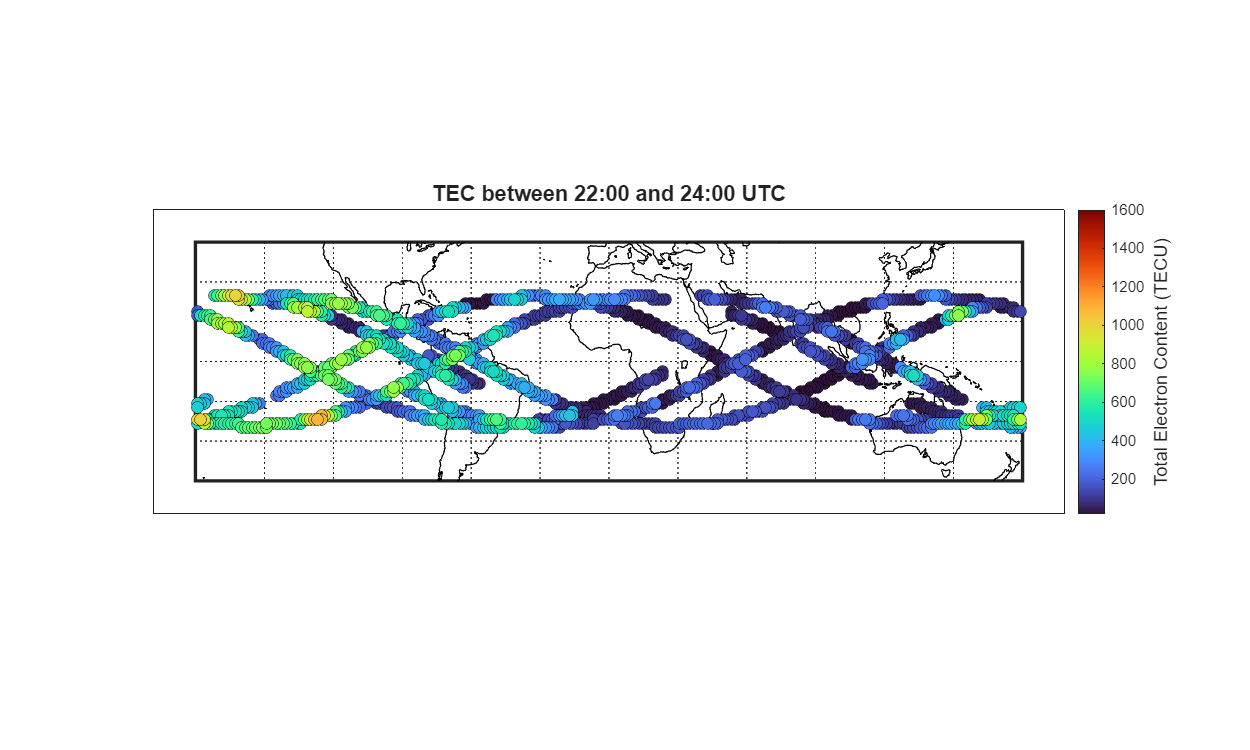

%% COSMIC TEC Map
clear min

%USER PARAMETERS
filter_quartiles  = false;
lower_pct         = 25;  
upper_pct         = 75;    


for target_hour = 23
    target_minute  = 00;
    time_tolerance = 60;
    minHour = target_hour-(time_tolerance/60);
    maxHour = target_hour+(time_tolerance/60);

    all_lat   = [];
    all_lon   = [];
    all_tec = [];

    for i = 1:length(COSMIC_data)

        file_hour            = COSMIC_data{i}.hour;
        file_min             = COSMIC_data{i}.minute;
        file_total_minutes   = file_hour * 60 + file_min;
        target_total_minutes = target_hour * 60 + target_minute;

        if abs(file_total_minutes - target_total_minutes) > time_tolerance
            continue
        end
        elevmask = COSMIC_data{i}.elevation < 0;
        lat = COSMIC_data{i}.GEO_lat_LEO(elevmask);
        lon = COSMIC_data{i}.GEO_lon_LEO(elevmask);
        tec  = COSMIC_data{i}.TEC(elevmask);

        if isempty(lat) || isempty(lon) || isempty(tec), continue; end
        if any(isnan(lat))   || any(isnan(lon))   || any(isnan(tec)),   continue; end

        all_lat   = [all_lat;   lat];
        all_lon   = [all_lon;   lon];
        all_tec = [all_tec; tec];
    end

    if isempty(all_lat)
        warning('No points found within the time window.');
        continue
    end

    %Quartile filter
    if filter_quartiles
        q_low  = prctile(all_tec, lower_pct);
        q_high = prctile(all_tec, upper_pct);
        keep   = all_tec >= q_low & all_tec <= q_high;
        all_lat   = all_lat(keep);
        all_lon   = all_lon(keep);
        all_tec = all_tec(keep);
        fprintf('Hour %02d: kept %d / %d points (%.0f-%.0f pctile)\n', ...
            target_hour, sum(keep), length(keep), lower_pct, upper_pct);
    end

    if isempty(all_lat)
        warning('No points remain after quartile filter for hour %02d.', target_hour);
        continue
    end

    %Spatial Grid Binning
    bin_size = 1.5;
    
    % Snap each point to nearest bin
    bin_lat_idx = floor(all_lat / bin_size) * bin_size + bin_size/2;
    bin_lon_idx = floor(all_lon / bin_size) * bin_size + bin_size/2;
    
    % Remove any NaN
    valid = ~isnan(bin_lat_idx) & ~isnan(bin_lon_idx) & ...
            all_lat >= -90 & all_lat <= 90 & ...
            all_lon >= -180 & all_lon <= 180;
    
    bin_lat_idx  = bin_lat_idx(valid);
    bin_lon_idx  = bin_lon_idx(valid);
    all_tec_valid = all_tec(valid);
    
    % Group by lat, lon bin
    [G, bin_lat, bin_lon] = findgroups(bin_lat_idx, bin_lon_idx);
    bin_tec = splitapply(@max, all_tec_valid, G);
    
    % Replace with binned versions
    all_lat = bin_lat;
    all_lon = bin_lon;
    cdata   = bin_tec;
    
    fprintf('Hour %02d: %d bins occupied (from %d raw points)\n', ...
        target_hour, length(cdata), sum(valid));
    %90-degree Longitude Bin Statistics
    
    % Assign 90-degree longitude bins
    lon_edges  = [-180, -90, 0, 90, 180];
    lon_labels = {'-180 to -90', '-90 to 0', '0 to 90', '90 to 180'};
    lon_bin    = discretize(all_lon, lon_edges);
    
    % Only keep points where bin is valid
    valid_bins = ~isnan(lon_bin);
    lon_bin_v  = lon_bin(valid_bins);
    cdata_v    = cdata(valid_bins);
    
    [G2, grp_lon] = findgroups(lon_bin_v);
    grp_mean   = splitapply(@mean,   cdata_v, G2);
    grp_median = splitapply(@median, cdata_v, G2);
    grp_p90    = splitapply(@(x) prctile(x, 90), cdata_v, G2);
    grp_max    = splitapply(@max,    cdata_v, G2);
    grp_count  = splitapply(@numel,  cdata_v, G2);

    % Global statistics
    global_mean = mean(cdata_v);
    global_max  = max(cdata_v);

    % Print results table
    fprintf('\n=== Hour %02d TEC Statistics by Longitude Bin ===\n', target_hour);
    fprintf('%-20s %8s %8s %8s %8s %6s\n', 'Lon Bin', 'Mean', 'Median', 'P90', 'Max', 'N');
    fprintf('%s\n', repmat('-', 1, 58));
    for g = 1:length(grp_mean)
        fprintf('%-20s %8.1f %8.1f %8.1f %8.1f %6d\n', ...
            lon_labels{grp_lon(g)}, ...
            grp_mean(g), grp_median(g), grp_p90(g), grp_max(g), grp_count(g));
    end
    fprintf('%-20s %8.1f %8s %8s %8.1f %6d\n', ...
        'Global', global_mean, '-', '-', global_max, length(cdata_v));
    fprintf('\n');

    bubble_size = 50;

    %Figure
    figure('Color', 'w', 'Position', [100 100 1000 600]);
    clf
    axesm('eqdcylin', 'MapLatLimit', [-45 45], 'MapLonLimit', [-180 180], ...
          'Frame', 'on', 'Grid', 'on')
    load coastlines
    geoshow(coastlat, coastlon, 'Color', 'k', 'LineWidth', 0.8)
    hold on
    %Sort by tec ascending
    [~, sort_idx] = sort(cdata, 'ascend');
    all_lat = all_lat(sort_idx);
    all_lon = all_lon(sort_idx);
    cdata = cdata(sort_idx);
    scatterm(all_lat, all_lon, bubble_size, cdata, 'filled', ...
        'MarkerFaceAlpha', 0.6, 'MarkerEdgeColor', 'k', 'LineWidth', 0.3);

    %Colorbar
    colormap("turbo")
    cb = colorbar;
    clim([20, 1600])
    cb.Label.String   = 'Total Electron Content (TECU)';
    cb.Label.FontSize = 11;
    title(sprintf('TEC between %02d:%02d and %02d:%02d UTC', ...
        minHour, target_minute, maxHour, target_minute), ...
        'FontSize', 13, 'FontWeight', 'bold')
end


while true; end
